addpath('G:\My Drive\Matlab_work\BC\Sea-Bird_Oxygen_Toolbox')
addpath('G:\My Drive\Matlab_work\BC\Sea-Bird-Toolbox')
addpath('G:\My Drive\Matlab_work\Functions\GSW')

cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year3')


% Configuration file was changed on xlmcon and then files were processed
% using Leah's processing pipeline 
% cal.E2 = 3.83e-2;
% cal.SOCnew % 0.387520789763739

cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year3')

% Casts 
cast01 = readSBScnv( 'uar0701001_KFabcdef.cnv' );
cast02 = readSBScnv( 'uar0701002_KFabcdef.cnv');
cast03 = readSBScnv( 'uar0701003_KFabcdef.cnv' );
cast04 = readSBScnv( 'uar0701004_KFabcdef.cnv' );
cast05 = readSBScnv( 'uar0701005_KFabcdef.cnv' );
cast06 = readSBScnv( 'uar0701006_KFabcdef.cnv' );
cast07 = readSBScnv( 'uar0701007_KFabcdef.cnv' );
cast08 = readSBScnv( 'uar0701008_KFabcdef.cnv' );
cast09 = readSBScnv( 'uar0701009_KFabcdef.cnv' );
cast10 = readSBScnv( 'uar0701010_KFabcdef.cnv' );


cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year3')
btl = readtable('Irminger_Sea-03_AR7-01_Discrete_Summary_KF.xlsx','TextType','string');
btl.Winkler_mLL = double(btl.Winkler_mLL);
btl.Discrete_Salinity_psu = double(btl.Discrete_Salinity_psu);

btlsum05 = btl(btl.Cast == 5,:);
btlsum06 = btl(btl.Cast == 6,:);
btlsum07 = btl(btl.Cast == 7,:);
btlsum08 = btl(btl.Cast == 8,:);
btlsum09 = btl(btl.Cast == 9,:);
btlsum10 = btl(btl.Cast == 10,:);

cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Bottle_Files\Year3')

btl05 = readtable('ar0701005_hyst.csv','TextType','string');

btl06 = readtable('ar0701006_hyst.csv','TextType','string');

btl07 = readtable('ar0701007_hyst.csv','TextType','string');

btl08 = readtable('ar0701008_hyst.csv','TextType','string');

btl09 = readtable('ar0701009_hyst.csv','TextType','string');

btl10 = readtable('ar0701010_hyst.csv','TextType','string');


% Join tables 

btlsum05 = join(btl05,btlsum05,'Keys',"Bottle");
btlsum06 = join(btl06,btlsum06,'Keys',"Bottle");
btlsum07 = join(btl07,btlsum07,'Keys',"Bottle");
btlsum08 = join(btl08,btlsum08,'Keys',"Bottle");
btlsum09 = join(btl09,btlsum09,'Keys',"Bottle");
btlsum10 = join(btl10,btlsum10,'Keys',"Bottle");

clear btl0* btl1* btl2*
clear btl 

btlsum_yr3 = [btlsum05; btlsum06; btlsum07; btlsum08;  btlsum09; btlsum10];

cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year3')
save Year3_Processed_KF cast* btl*

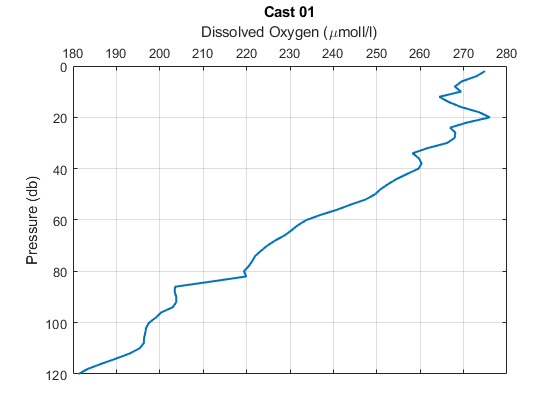

figure
plot(cast01.sbeox0mL_L*44.661,cast01.pm,'Linewidth',1.5)
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumoll/l)'); ylabel('Pressure (db)')
grid on
title('Cast 01')

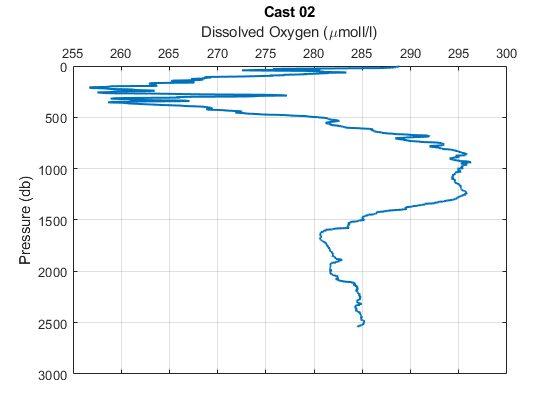


figure
plot(cast02.sbeox0mL_L*44.661,cast02.pm,'Linewidth',1.5)
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumoll/l)'); ylabel('Pressure (db)')
grid on
title('Cast 02')

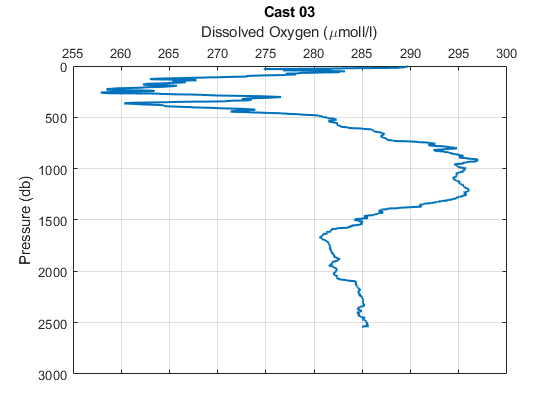


figure
plot(cast03.sbeox0mL_L*44.661,cast03.pm,'Linewidth',1.5)
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumoll/l)'); ylabel('Pressure (db)')
grid on
title('Cast 03')

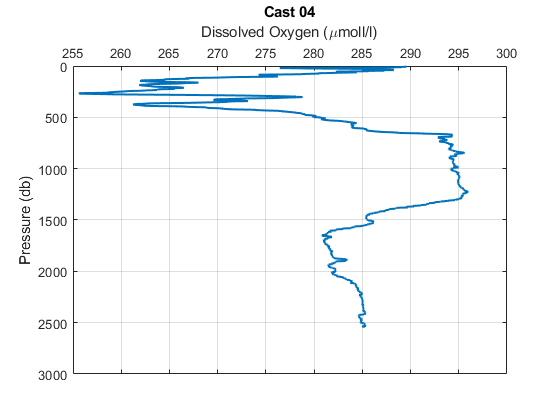


figure
plot(cast04.sbeox0mL_L*44.661,cast04.pm,'Linewidth',1.5)
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumoll/l)'); ylabel('Pressure (db)')
grid on
title('Cast 04')

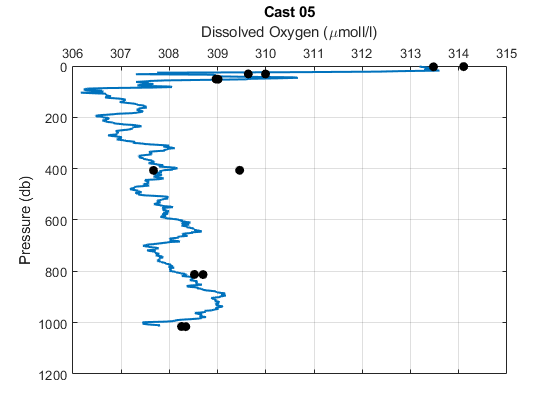


figure
plot(cast05.sbeox0mL_L*44.661,cast05.pm,'Linewidth',1.5)
hold on
plot(btlsum05.Winkler_mLL*44.661,btlsum05.PrDM,'ok','MarkerFaceColor','k')
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumoll/l)'); ylabel('Pressure (db)')
grid on
title('Cast 05')

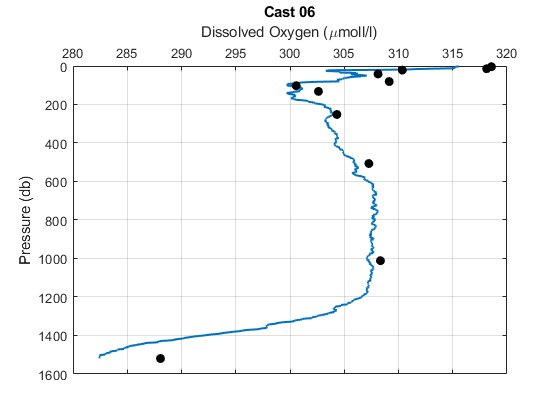


figure
plot(cast06.sbeox0mL_L*44.661,cast06.pm,'Linewidth',1.5)
hold on
plot(btlsum06.Winkler_mLL*44.661,btlsum06.PrDM,'ok','MarkerFaceColor','k')
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumoll/l)'); ylabel('Pressure (db)')
grid on
title('Cast 06')

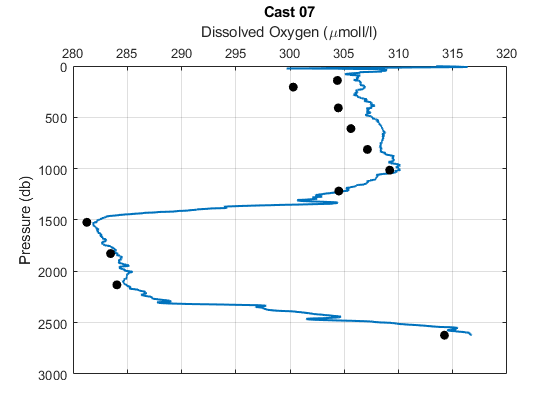


figure
plot(cast07.sbeox0mL_L*44.661,cast07.pm,'Linewidth',1.5)
hold on
plot(btlsum07.Winkler_mLL*44.661,btlsum07.PrDM,'ok','MarkerFaceColor','k')
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumoll/l)'); ylabel('Pressure (db)')
grid on
title('Cast 07')

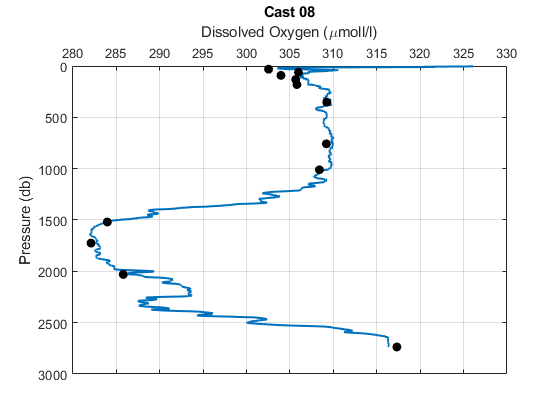


figure
plot(cast08.sbeox0mL_L*44.661,cast08.pm,'Linewidth',1.5)
hold on
plot(btlsum08.Winkler_mLL*44.661,btlsum08.PrDM,'ok','MarkerFaceColor','k')
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumoll/l)'); ylabel('Pressure (db)')
grid on
title('Cast 08')

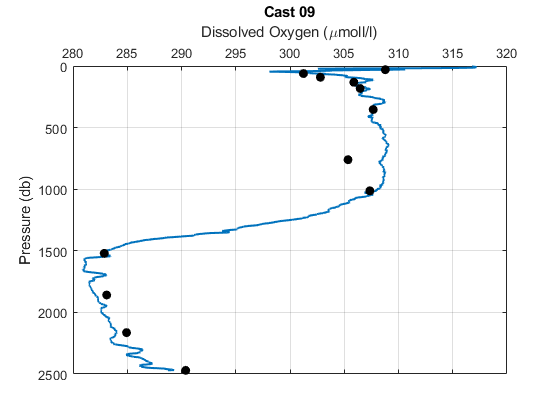


figure
plot(cast09.sbeox0mL_L*44.661,cast09.pm,'Linewidth',1.5)
hold on
plot(btlsum09.Winkler_mLL*44.661,btlsum09.PrDM,'ok','MarkerFaceColor','k')
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumoll/l)'); ylabel('Pressure (db)')
grid on
title('Cast 09')

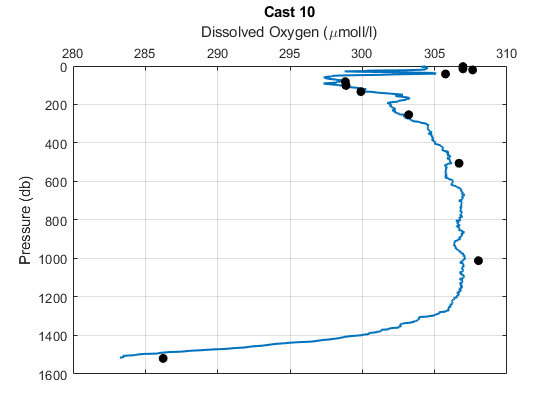


figure
plot(cast10.sbeox0mL_L*44.661,cast10.pm,'Linewidth',1.5)
hold on
plot(btlsum10.Winkler_mLL*44.661,btlsum10.PrDM,'ok','MarkerFaceColor','k')
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumoll/l)'); ylabel('Pressure (db)')
grid on
title('Cast 10')